file_m = fopen("C:\a_PhD Research\RUL\Codes\HI\m1t3_ta_y.txt", 'r');
data = textscan(file_m, '%f');
fclose(file_m);

data = cell2mat(data);
healthIndicator = data;

healthIndicator= healthIndicator-min(healthIndicator);
healthIndicator = healthIndicator(11:550);

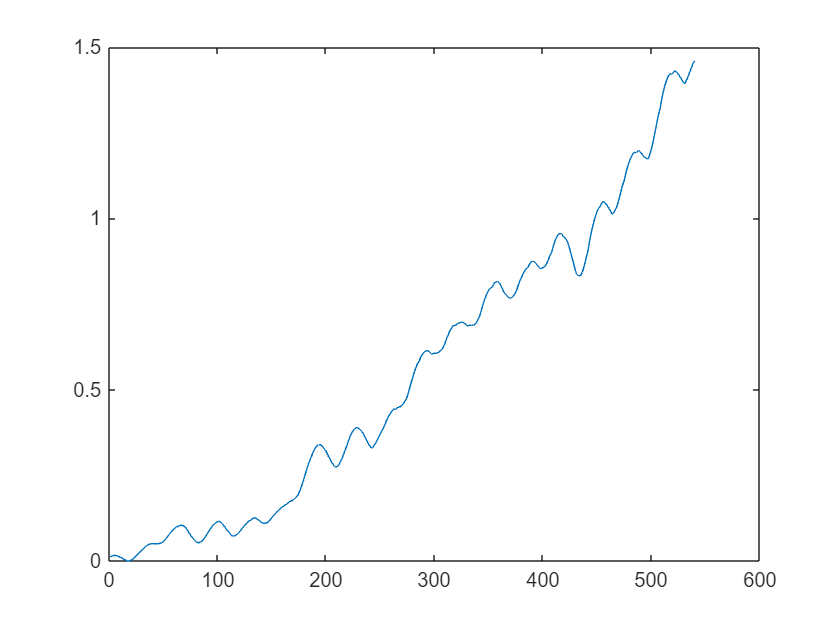

plot(healthIndicator)

threshold = healthIndicator(end);
threshold

threshold = 1.4591

mdl = exponentialDegradationModel(...
    'Theta', 0.4757, ...
    'ThetaVariance', 0.0361, ...
    'Beta', 0.0032, ...
    'BetaVariance', 4.18e-07, ...
    'Phi', -1, ...
    'NoiseVariance', (0.1*threshold/(threshold + 1))^2, ...
    'SlopeDetectionLevel', 0.05);

mdl.Prior

ans = struct with fields:
            Theta: 0.4757
    ThetaVariance: 0.0361
             Beta: 0.0032
     BetaVariance: 4.1800e-07
              Rho: 0


timeUnit = '\times 5 day';

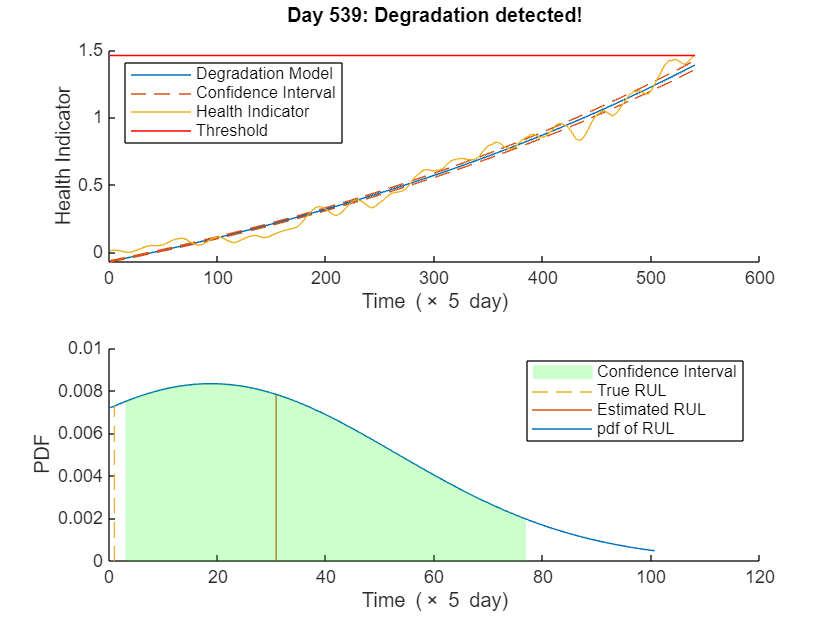

% Keep records at each iteration
totalDay = length(healthIndicator) - 1;
estRULs = zeros(totalDay, 1);
trueRULs = zeros(totalDay, 1);
CIRULs = zeros(totalDay, 2);
pdfRULs = cell(totalDay, 1);

% Create figures and axes for plot updating
figure
ax1 = subplot(2, 1, 1);
ax2 = subplot(2, 1, 2);

for currentDay = 1:totalDay
    
    % Update model parameter posterior distribution
    update(mdl, [currentDay healthIndicator(currentDay)])
    
    % Predict Remaining Useful Life
    [estRUL, CIRUL, pdfRUL] = predictRUL(mdl, ...
                                         [currentDay healthIndicator(currentDay)], ...
                                         threshold);
    trueRUL = totalDay - currentDay + 1;
    
    % Updating RUL distribution plot
    helperPlotTrend(ax1, currentDay, healthIndicator, mdl, threshold, timeUnit);
    helperPlotRUL(ax2, trueRUL, estRUL, CIRUL, pdfRUL, timeUnit)
    
    % Keep prediction results
    estRULs(currentDay) = estRUL;
    trueRULs(currentDay) = trueRUL;
    CIRULs(currentDay, :) = CIRUL;
    pdfRULs{currentDay} = pdfRUL;
    
    % Pause 0.1 seconds to make the animation visible
    pause(0.1)
end

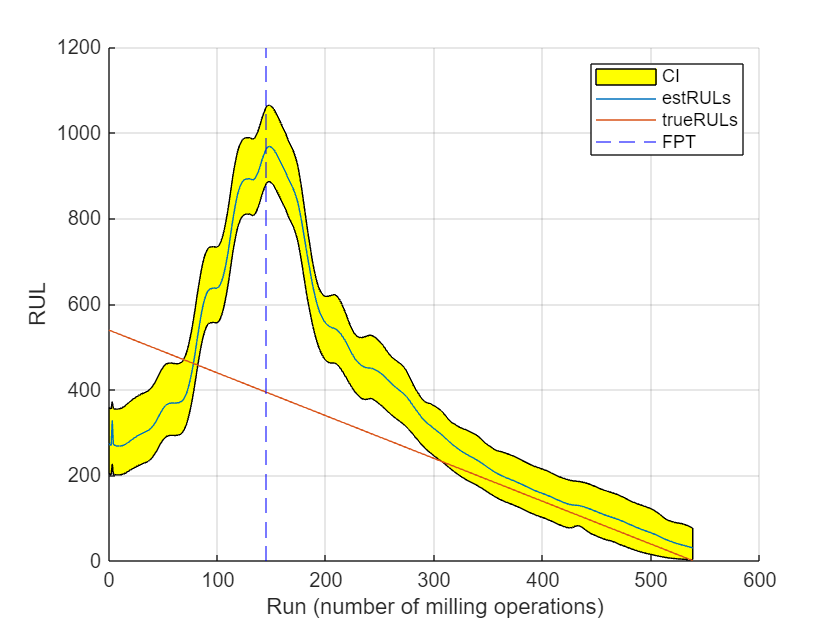

x=0:1:538;
ub = CIRULs(:, 2)';
lb = CIRULs(:, 1)';
figure
hold all
patch([x fliplr(x)], [ub fliplr(lb)], 'y', 'DisplayName', 'CI')
plot(x, estRULs', 'DisplayName','estRULs')
plot(x, trueRULs', 'DisplayName','trueRULs')
xline(145, '--b', 'DisplayName','FPT');
xlabel('Run (number of milling operations)')
ylabel('RUL')
%subplot(2,1,2)
grid on
legend
saveas(gcf, 'M1T3.pdf')

rmse(trueRULs, estRULs)

ans = 216.4651